# lTEMPLATE FOR DATA LABEL

Version: 2.0

Date: 1/08/2022 

## EXPLANATION:

 At the beginning of each experiment you have to start from the STEP 1.

For the second suture or more from the same experiment, you have to start from the STEP 4 for each suture.

___________________

## STEP 1:   INITIALIZE THE PROJECT WITH THE NUMBER OF THE EXPERIMENT

- **Write the number of the experiment (line 8)**

% DO NOT CHANGE %--------------------
clc
clear all
%-----------------------------------


%%  WRITE HERE THE NUMBER OF THE EXPERIMENT   %%
experimiento = 2;  % <-----------------
%%  WRITE HERE THE NAME OF THE FILE   %%
file_name = 'fragile3 fishing'; %   <------------
coupon_name = 'normal'; %   <------------
status = 'fail'; %   <------------

%%%%%%%

    **2. Run this section (one click on the blue lines on the left side of the number of the lines)**

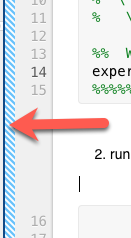

Do not change anything else in this step

% DO NOT CHANGE %-----------------------
carpetaExp = sprintf('%s_exp%d_%s_%s',file_name,experimiento,coupon_name,status);
RawFiles = strcat(pwd,'\','\RawFiles');
SutureFiles = strcat(pwd,'\',carpetaExp);
mkdir(SutureFiles);

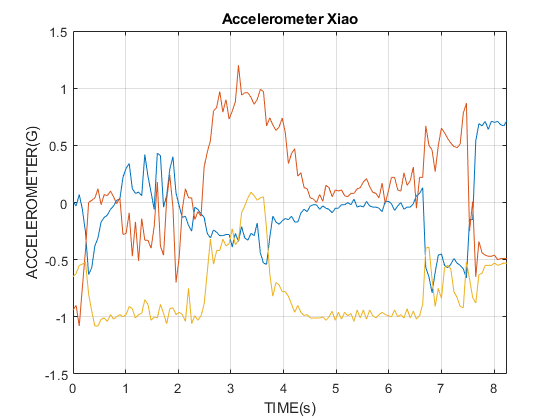

xiao_table = fullfile(RawFiles, sprintf(file_name));
xiao_Signals = readtable(xiao_table);
xiao_Signals.coupon = repmat(coupon_name, height(xiao_Signals), 1);
writetable(xiao_Signals, xiao_table);
xiao_Signals.status =repmat(status, height(xiao_Signals), 1);
writetable(xiao_Signals, xiao_table);
%f = 50;
T = 0.0589;

figure()
total_time1_xiao = length(xiao_Signals.ACX)*T;
time_vector1_xiao = linspace(0,total_time1_xiao,length(xiao_Signals.ACX));
plot(time_vector1_xiao,xiao_Signals.ACX,time_vector1_xiao,xiao_Signals.ACY,time_vector1_xiao,xiao_Signals.ACZ)
title ('Accelerometer Xiao')
ylabel('ACCELEROMETER(G)')
xlabel('TIME(s)')
xlim tight
grid on

%-------------------------------------

## _____________________   START FROM HERE FOR EACH SUTURE

__________

## STEP 2:  FIND THE KEY POINTS FOR THE SUTURE

- **Wirte the number of the SUTURE**

The number of the suture starts with 1 for the first one of each experiment

%%%%% DONT CHANGE %%%%%%%
experiment = 1; % <-----------------

%%%%%% IGNORE THIS LINE - DONT CHANGE ANYTHING%%%%
% load VarToload.mat;

    **    3. Watch the video and note the time where the important things happen**

%%%%% WRITE THE RANGE OF VALUES HERE %%%%%%%
% .. = [MINUTE SECOND]
%%%%%%%%%%%%% DONT CHANGE %%%%%%%%%%%%%%%%%%%
startTime = [0 0.1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% VUELTAS %%%%%%%%%%%%%%%%%%%%%
% YOU CAN ADD OR REMOVE THE PACKAGE OF LINES IF IT'S NECESSARY 
% WRITE THE TIME WHEN THE CLEANING STARTS

startCleaning = [0 1.80];
finalcleaning = [0 4.20];
% orientacionVueltas(numInjecting) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
%--

inicioInjecting = [0 6.70];
finalInjecting = [0 8.0];
% orientacionVueltas(numInjecting) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
%--

% %--
% numVuelta = 2;
% inicioVueltas(numVuelta,:) = [0 3.0];
% finalVueltas(numVuelta,:) = [0 3.80];
% orientacionVueltas(numVuelta) = 0;
% %--

% %--
% numVuelta = 3;
% inicioVueltas(numVuelta,:) = [5 28.23];
% finalVueltas(numVuelta,:) = [5 28.65];
% orientacionVueltas(numVuelta) = 1; % 0 'abajo' o 1 'arriba' segun la orientacion;
% %--


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% FIN VUELTAS %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
finaltime = [0 8.1];
tiempofinalsutura = ConvTime(finaltime);


**4. Run this section (one click on the blue lines on the left side of the number of the lines)**

**5. CHECK THE GRAPH WITH COLORS IF EVERYTHING IS FINE**

DO NOT CHANGE FROM HERE

% DO NOT CHANGE %-----------------------
%%%%%%%%%%%%%%%%% no cambiar guarado de variables %%%%%%%%%%%%%%%%
SutureFolder = fullfile(strcat(SutureFiles));
mkdir(SutureFolder);

mkdir(SutureFolder, "log")

mkdir(SutureFolder, "img")

mkdir(SutureFolder, "Cleaning")

mkdir(SutureFolder, "Injecting")

mkdir(SutureFolder, "Negative")

% mkdir(strcat(SutureFolder,'\Cleaning'),"Cleaning")
% mkdir(strcat(SutureFolder,'\Injecting'),"Injecting")
% mkdir(strcat(SutureFolder,'\Cleaning'),"Vueltas")
% mkdir(strcat(SutureFolder,'\Cleaning'),"VueltasAdelante")
% mkdir(strcat(SutureFolder,'\Cleaning'),"VueltasAtras")

%%%% SAVE CLEANING %%%%%

[cleaning_signal] = Guardado(startCleaning,finalcleaning,xiao_Signals);
cleaning_data = fullfile(strcat(SutureFolder,'\Cleaning'), sprintf('Cleaning_%d_%s_%s_%s.mat',experimiento,file_name,coupon_name,status));
save(cleaning_data,"cleaning_signal","-mat");
% [Positive_Aguja_APL] = Guardado(startCleaning,finalcleaning,xiao_Signals);
% Aguja = fullfile((strcat(SutureFolder,'\Positive\AgujaEntraSale')),sprintf('Positive_Aguja_Suture%d_exp%d.mat',experiment,experimiento));
% save(Aguja,'Positive_Aguja_APL');


%%%% SAVE INJECTING %%%%%
[injecting_signal] = Guardado(inicioInjecting,finalInjecting,xiao_Signals);
injecting_data = fullfile(strcat(SutureFolder,'\Injecting'), sprintf('Injecting_%d_%s_%s_%s.mat',experimiento,file_name,coupon_name,status));
save(injecting_data,"injecting_signal","-mat");


%%% guarda el rango desde el inicio de la sutura al final %%%
% [SutureRange_APL] = Guardado(startTime,finaltime,xiao_Signals);
% Range_Suture = fullfile(strcat(SutureFolder,'\log'), sprintf('Range_Suture%d_exp%d.mat',experiment,experimiento));
% save(Range_Suture,"SutureRange_APL","-mat");
% %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%% NO MODIFICAR %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% conversion a segundo y guardado de variables
inicios=[];
finales = [];
% for n=2:length(orientacionVueltas)+1
%     for j=1:n-1
% 
%     end
% end

  
finales(1) = ConvTime(startTime);
inicios(1) = ConvTime(startCleaning);
finales(2) = ConvTime(finalcleaning);
inicios(2) = ConvTime(inicioInjecting);
finales(3) = ConvTime(finalInjecting);
sizeOfinicios = length(inicios);             
inicios(sizeOfinicios+1) = ConvTime(finaltime);
% for n=3:length(finalInjecting)+2
%     for j=1:n-2
%     tiempo = ConvTime(finalInjecting(j,:));
%     finales(n) = tiempo;
%     end
% end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Grafica para comprobar que los puntos quedaron bien marcado y guardar
%%%% negativos %%%%%%
figure()
for n=1:numel(inicios)
    a_num = inicios(n);
    disp(a_num)
    b_num = finales(n);
    [useless_data] = GuardadoNegativo(b_num,a_num,xiao_Signals);
    Range_Suture_negative = fullfile(strcat(SutureFolder,'\Negative'), sprintf('useless_Negative%d_%s_%s_%s.mat',n,file_name,coupon_name,status));
    save(Range_Suture_negative,"useless_data","-mat");
end    

    30



     ACX      ACY      ACZ       GX        GY        GZ      PRESS1    PRESS2    PRESS3           DATE            coupon    status
    _____    _____    _____    ______    ______    ______    ______    ______    ______    ___________________    ______    ______

     0.01    -0.94    -0.65     27.37    -20.79     24.92      0         0         0       21/12/2022 09:17:30    normal     fail 
    -0.03     -0.9    -0.62    -30.38     -15.4     42.49      0         0         0       21/12/2022 09:17:30    normal     fail 
     0.07    -1.08    -0.55       -63    -56.49     54.39      1   

   113



     ACX      ACY      ACZ       GX        GY        GZ      PRESS1    PRESS2    PRESS3           DATE            coupon    status
    _____    _____    _____    ______    ______    ______    ______    ______    ______    ___________________    ______    ______

    -0.12     0.43    -0.89     16.59       8.4     -4.62     125       873         0      21/12/2022 09:17:40    normal     fail 
    -0.17     0.47    -0.96     17.29      -0.7      -8.4     130       868         0      21/12/2022 09:17:41    normal     fail 
    -0.17     0.23     -0.9      8.33     10.99     -9.45       0  

   137



    ACX      ACY      ACZ      GX       GY       GZ      PRESS1    PRESS2    PRESS3           DATE            coupon    status
    ____    _____    _____    _____    _____    _____    ______    ______    ______    ___________________    ______    ______

    0.71    -0.47    -0.55     0.56     7.91     5.25      0         0         0       21/12/2022 09:17:49    normal     fail 
     0.7    -0.46    -0.53    -1.05    -1.54    18.48      0         0         0       21/12/2022 09:17:49    normal     fail 
    0.71     -0.5    -0.55     1.96     4.41      4.2      0         0         0   

    30

     1

   113

    71

   137

   135



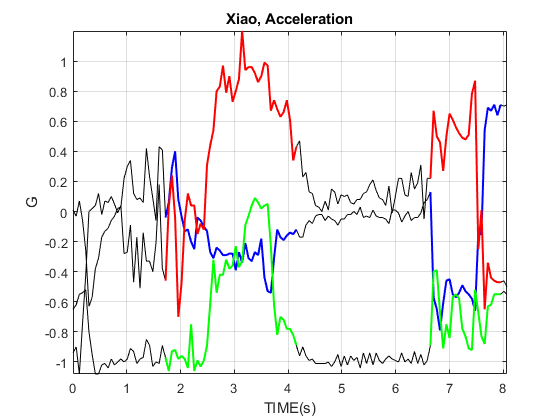

    30

     1

   113

    71

   137

   135



    30

     1

   113

    71

   137

   135



z=GuardarGraficasPDF(xiao_Signals,time_vector1_xiao,inicios,finales,SutureFolder);

AllVar = fullfile(strcat(SutureFolder,'\log'), sprintf('AllVar_%s_%s_%s.mat',file_name,coupon_name,status));
save(AllVar,"-mat");
Array_iniFin = fullfile(strcat(SutureFolder,'\log'), sprintf('Arrays_%s_%s_%s.mat',file_name,coupon_name,status));
save(Array_iniFin,"-mat");